Companion software for "Volker Ziemann, *Physics and Finance, Springer, 2021*" ([https://link.springer.com/book/10.1007/978-3-030-63643-2](https://link.springer.com/book/10.1007/978-3-030-63643-2))

# Elliptic-curve arithmetic (Section 12.7)

Volker Ziemann, 211116, CC-BY-SA-4.0

In this example we illustrate the group structure of the points under the addition, defined by Equation 12.32 and 12.33 by successively adding a generator point `G` to itself, where all artithmetic is based on an integer field defined by a prime number` p`. The details can be found in Section 12.7.

We first define the prime number `p` of the base field for the calculations and specify the elliptic curve `f(),` as defined in Equation 12.30 through its coefficients a and b. All numbers are then integers between `0` and `p-1`. 

p=113;     % prime
a=0; b=7;  % coefficient of the elliptic curve
f=@(x)powermod(x.^3+a*x+b,1,p);   % elliptic curve

We now try to find a suitable generator point G by specifying its x-coordinate `xstart` and use the elliptic curve `f2()` to calculate its y-coordinate `ystart`. 

xstart=13         % try 1, 7, 13, 15, 95, 111

xstart = 13

ystart=f(xstart)

ystart = 57

Then we probe whether `ystart` is the square of some value k. In oher words, we try to find a value y that actually satisfies Equation 12.30. If we find one, we use it to define the generator point `G`, otherwise we give a warning and terminate the script.

for y=0:p-1
  y2=powermod(y,2,p);  % square modulo p
  if y2==ystart
    G=[xstart,y]       % generator point G
    break
  end
end

G =     13    31


if ~exist('G','var') disp('No generator point found!'); return; end

Now we plot the generator point as a red asterisk and then plot all points belonging to the group, which we determine by consecutively adding the generator G to itself, include the newly-found points in the array data, until we obtain a point at infinity. It would reproduce any point, when added to it and therefore terminates the procedure. Before leaving the search we also report the number of points found, which is the order of the group.

ishow=1;
Pc=G;
data(1,:)=G;
plot(G(1),G(2),'r*','MarkerSize',10); hold on
for k=2:2*p
  Pc=ECadd_p(Pc,G,a,b,p);
  data(k,:)=Pc;
  if Pc(2) == Inf, disp(['Order of group = ',num2str(k)]); ishow=0; end
  if ishow==0, break; end
end

Order of group = 114


Finally we display all points that belong to the group.

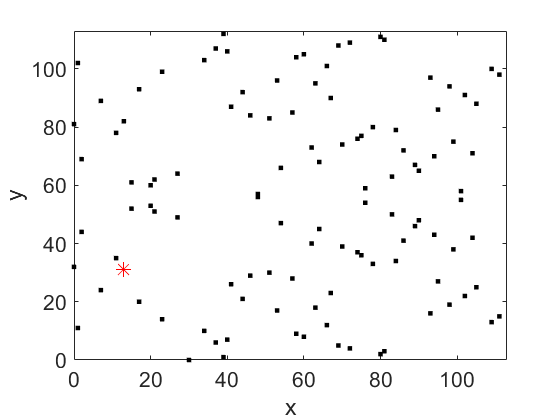

plot(data(2:end,1),data(2:end,2),'k.','MarkerSize',10)
xlim([0,p]); ylim([0,p])
xlabel('x'); ylabel('y')
set(gca,'FontSize',16)

Try out different parameters, epsecially different `xstart` values, which will lead to different generator points `G` and consequently different order of the groups; try xstart=1,7,13,15, 95, 111, which will give produce some G, but other starting coordinates will not.

Elliptic-curve cryptographic systems rely on the fact that it is rather straightforward to add the publicly known generator `G` any number of times `m` to obtain a point `P`, but it is well-nigh impossible to determine m from knowing `P` (and `G`), at least for very large prime numbers, which then lead to very large groups.

## Appendix

The function `ECadd_p()` receives two points `Pa `and `Pb` on an elliptic curve, which is specified by parameters `a` and `b`, as well as the base` p`. It returns a new point on the same curve `Pc` that is calculated from Equation 12.32 and 12.33. The handling of special cases is discussed in Section 12.7.

function Pc=ECadd_p(Pa,Pb,a,b,p)
if Pa(2) == Inf, Pc=Pb; return; end
if Pb(2) == Inf, Pc=Pa; return; end
if Pa(1) == Pb(1) & Pa(2) ~= Pb(2), Pc=[0,Inf]; return; end
if Pa(1) == Pb(1)
  if Pa(2) == Pb(2) & Pa(2) == 0
    Pc=[0,Inf];    
    return
  else
    denominv=powermod(2*Pa(2),p-2,p);  % was 1
    s=powermod((3*Pa(1)*Pa(1)+a)*denominv,1,p);
  end
else
  denominv=powermod(Pb(1)-Pa(1),p-2,p);
  s=powermod((Pb(2)-Pa(2))*denominv,1,p);
end
Pc(1)=powermod(s*s-Pa(1)-Pb(1),1,p);
Pc(2)=powermod(-s*(Pc(1)-Pa(1))-Pa(2),1,p);
end